# Jeremy Human Exclusion Video Processing Project

**Pho Hale, created 03-12-2020**

**Goal: Given an input video of Jeremy running a rat on his circular water table, construct a vector of pairs of frames (start, end) to exclude from analysis because they have Jeremy in them.**

## Input Settings:

currentFolder = pwd
videoFrameGateRect = [319.913260485224 9.09676368265632 17.174890796144 15.3794414144288];
curr_files_path = '..\Peekay_200116_143440';
curr_video_file.filename = 'Peekay_20200116_143605803.avi';
curr_video_file.relative_file_path = fullfile("..\Peekay_200116_143440\Peekay_20200116_143605803.avi");
[~,curr_video_file.basename, curr_video_file.extension] = fileparts(curr_video_file.filename)
v = VideoReader(curr_video_file.relative_file_path);
curr_video_file.full_parent_path = v.Path;
curr_video_file.full_path = fullfile(curr_video_file.full_parent_path, curr_video_file.filename);

% Frames:
% startFrameIndex = 1;
% endFrameIndex = round(v.NumFrames/16);
currShiftIndex = 2; % What set of frames to load (to conserve memory)
startFrameIndex = 1 + ((currShiftIndex-1)*round(v.NumFrames/16));
endFrameIndex = (currShiftIndex*round(v.NumFrames/16));

frameIndexes = startFrameIndex:endFrameIndex;
selectedNumberOfFrames = length(frameIndexes);

## Output Settings:

curr_output_data_path = fullfile(curr_video_file.full_parent_path,"Data"); % Location to save the data
mkdir(curr_output_data_path);

curr_output_settings.video_name_string = curr_video_file.basename;
% curr_output_settings.video_frame_string = sprintf("frames_%d-%d",num2str(startFrameIndex),num2str(endFrameIndex));
curr_output_settings.video_frame_string = sprintf("frames_%d-%d",startFrameIndex,endFrameIndex);
curr_output_settings.frames_data_output_suffix = 'outputCache';

curr_output_settings.final_output_name = join([curr_output_settings.frames_data_output_suffix, curr_output_settings.video_name_string, curr_output_settings.video_frame_string, ".mat"],"_");
curr_output_settings.final_output_path = fullfile(curr_output_data_path, curr_output_settings.final_output_name)
%curr_output_path = 

## Read the frames

frames = read(v,[startFrameIndex endFrameIndex],"native");

## Pre-allocate output structures

greyscale_frames = zeros([v.Height, v.Width, selectedNumberOfFrames], 'uint8');
% processedFrames = zeros([v.Height, v.Width, selectedNumberOfFrames], 'uint8');
processsed.mean_intensity = zeros([1, selectedNumberOfFrames], 'uint8');

## Build Grayscale Frames:

% Pre-allocate the greyscale_frames output
% greyscale_frames(1:selectedNumberOfFrames) = struct('cdata',zeros(v.Height,v.Width,1,'uint8'),'colormap',[]);
% Read one frame at a time. 
parfor k = 1 : selectedNumberOfFrames
%     greyscale_frames(k).cdata = rgb2gray(frames(:,:,:,k));
    greyscale_frames(:,:,k) = rgb2gray(frames(:,:,:,k));
end

## Get Frequency Paramaters:

Fs = v.FrameRate;
dt = 1/Fs;
selectedDuration = selectedNumberOfFrames * dt % Seconds
StopTime = dt * length(frameIndexes);
% t = (0:dt:StopTime-dt)';
t = ((frameIndexes'-1)*dt);
% relative_t_into_video = (0:dt:StopTime-dt)';

N = size(t,1);

% Frequency Specs:
dF = Fs/N; % Hertz
f = (-Fs/2):dF:((Fs/2)-dF); % Hertz

## Save the frames incase something happens:

save(curr_output_settings.final_output_path,'frames', 'greyscale_frames','-v7.3');

% Drop some frames
% frames = frames(:,:,:,startFrameIndex:16:endFrameIndex);

## Compute the total mean intensity for all frames:

mean_per_frame = mean(greyscale_frames, [1,2]);
size(mean_per_frame)
mean_per_frame = squeeze(mean_per_frame); %% Remove dimensions of length 1
% mean_per_frame_smoothed = smoothdata(mean_per_frame,'movmean');
plot(mean_per_frame);
xlabel('Time Into Video [sec]')
title('Mean Total Frame Intensity')
hold on;
% plot(mean_per_frame_smoothed)

%% Select small portion of the video frame for all frames.
% gate_indicator_frame_region = frames(320:335,9:20,:,:);
% [321.48125 7.50000000000008 15.477083333333 10.3499999999998]
% 320+15
% 7.5+10
% height is 850
gate_indicator_frame_region = greyscale_frames(9:18,320:335,:);
% implay(gate_indicator_frame_region)
% gate_indicator_frame_region
size(gate_indicator_frame_region)
% region_mean_per_frame = mean(gate_indicator_frame_region, [1,2]);
% region_mean_per_frame = region_mean_per_frame(1,1,:);
% region_mean_per_frame = mean(gate_indicator_frame_region, [1,2]);
region_mean_per_frame = min(gate_indicator_frame_region,[], [1,2]);
size(region_mean_per_frame)
region_mean_per_frame = squeeze(region_mean_per_frame); %% Remove dimensions of length 1
size(region_mean_per_frame)
% region_mean_per_frame_smoothed = smoothdata(region_mean_per_frame,'movmean');

% 0.65 before
% 0.26 after

% Remove high-frequency noise:
% https://www.mathworks.com/matlabcentral/answers/230702-how-to-find-consecutive-values-above-a-certain-threshold
threshold = 120;
num_consecutive_frames_above_threshold = 40; % at 20fps that's 2 seconds
% Find logical vector where A > threshold
binaryVector = region_mean_per_frame > threshold;
% Label each region with a label - an "ID" number.
[labeledVector, numRegions] = bwlabel(binaryVector);
% Measure lengths of each region and the indexes
measurements = regionprops(labeledVector, region_mean_per_frame, 'Area', 'PixelValues');
% Find regions where the area (length) are 3 or greater and
% put the values into a cell of a cell array
for k = 1 : numRegions
  if measurements(k).Area >= num_consecutive_frames_above_threshold
    % Area (length) is num_consecutive_frames_above_threshold or greater, so store the values.
    ca{k} = measurements(k).PixelValues; % Stores the frames where such is the case?
    
  end
end
% Display the regions that meet the criteria:
celldisp(ca)

% Draw the thing
temp = double(region_mean_per_frame);
temp(~binaryVector) = 0;

numRegions

numRegions = 1

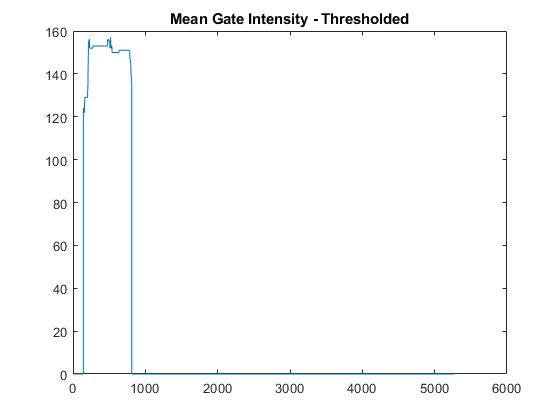

hold off;

plot(temp);
title('Mean Gate Intensity - Thresholded')

% region_mean_per_frame = reshape(region_mean_per_frame,[size(region_mean_per_frame,3),1]);
plot(region_mean_per_frame_smoothed);
xlabel('Time Into Video [sec]')
title('Mean Gate Intensity')

## Plot the frequency spectrum and histogram:

%%Fourier Transform:
region_mean_per_frame_FREQ = fft(region_mean_per_frame);
%%Plot the spectrum:
figure;
plot(abs(region_mean_per_frame_FREQ)/N);
xlabel('Frequency (in hertz)');
title('Magnitude Response');

fig = figure(1);
clf
h = plot(frameIndexes, region_mean_per_frame_smoothed);
xlabel('Frame Index');
title('Region Intensity');
dualcursor;

% datacursor_update_function = @(~,event_obj) {['Time: ','test'],['Amplitude: ','test']};
% dcm_obj = datacursormode(fig)
% set(dcm_obj,'DisplayStyle','datatip','SnapToDataVertex','on','Enable','on')
% set(dcm_obj,'UpdateFcn', @datacursor_update_function)

%c_info = getCursorInfo(dcm_obj);

% function output_txt = datacursor_update_function(~,event_obj)
%     % ~            Currently not used (empty)
%     % event_obj    Object containing event data structure
%     % output_txt   Data cursor text
%     pos = get(event_obj,'Position');
%     output_txt = {['Time: ',num2str(pos(1))],...
%     	      ['Amplitude: ',num2str(pos(2))]};
% end

## Play Video:

% PreCallBack = @(~,~) disp('Pause the video here');
% PostCallBack = @(~,~)disp('Play the video here');
% F = figure();
% H = uicontrol(F,'Style','slider','Position',[81,54,200,23]);
% addlistener(H, 'Value', 'PostSet',PostCallBack);
% addlistener(H, 'Value', 'PreSet', PreCallBack);

% Signal Analyzer:
% signalAnalyzer(region_mean_per_frame,"SampleRate",Fs);
% signalAnalyzer(region_mean_per_frame_smoothed,"SampleRate",Fs);


% Video Player
vidPlayCallbacks.PreFrameUpdate = @(~,~) disp('Pre Frame changed!');
vidPlayCallbacks.PostFrameUpdate = @(~,~) disp('Post Frame changed!');

%vidPlayer.addNewDataListener()
vidPlayer.DataSource.getFrameData()

vidPlaySourceType = vidPlayer.DataSource.Type;
if vidPlaySourceType == "Workspace"
    % Loaded from a workspace variable!
    vidPlaySourceWorkspaceVariableName = vidPlayer.DataSource.Name;
    vidPlaySourceWorkspaceVariableValue = eval(vidPlaySourceWorkspaceVariableName);
else
    % Don't know what to do with videos loaded from disk
    disp("Unhandled type!");
end



vidPlayer = implay(greyscale_frames, v.FrameRate);
vidPlayer.addlistener(vidPlayCallbacks.FrameUpdate)
%vidPlayer.DataSource.Controls.CurrentFrame

%vidPlayer.viewMenuCallback
% Jump to frame:
vidPlayer.DataSource.Controls.jumpTo(10);

addlistener(H, 'Value', 'PostSet',PostCallBack);
addlistener(H, 'Value', 'PreSet', PreCallBack);
% svp.vidPlayer.Parent.
